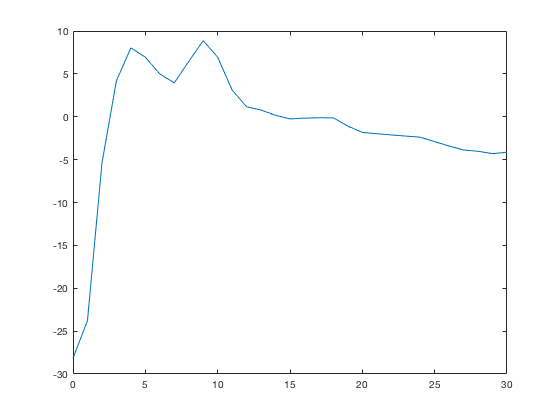

open /Users/air/Desktop/channel1.fig % path to the channel PSD file
% open /Users/air/Desktop/Unfocused_416-451.fig

D=get(gca,'Children'); %get the handle of the line object
XData=get(D,'XData'); %get the x data
YData=get(D,'YData'); %get the y data
Data=[XData' YData']; %join the x and y data on one array nx2

figure
plot(XData, YData) % replot the graph to check

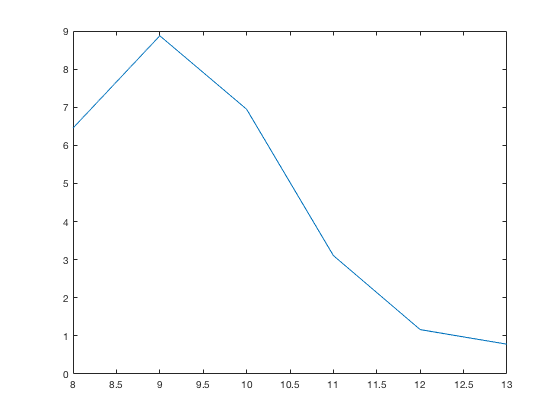


% integrate to get the features: 
% alpha energy, (8-13 Hz)
% beta energy, (14-30 Hz)
% theta energy, (4-8 Hz)
% ratio between Ea and Eb, R = Ea / Eb
% (ignore gamma, delta energy)

% Calculate alpha energy
boundA = (XData >= 8 & XData <= 13); % freq range of alpha wave
Fa = XData(boundA);
Pa = YData(boundA); % power density range of alpha wave
Ea = trapz(Fa, Pa); % integrate to get energy of alpha wave

figure
plot(Fa, Pa)

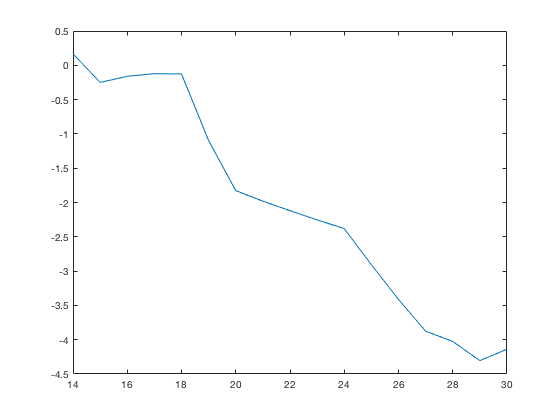


% Calculate beta energy
boundB = (XData >= 14 & XData <= 30); % freq range of beta wave
Fb = XData(boundB);
Pb = YData(boundB); % power density range of beta wave
Eb = trapz(Fb, Pb); % energy of beta wave

figure
plot(Fb, Pb)

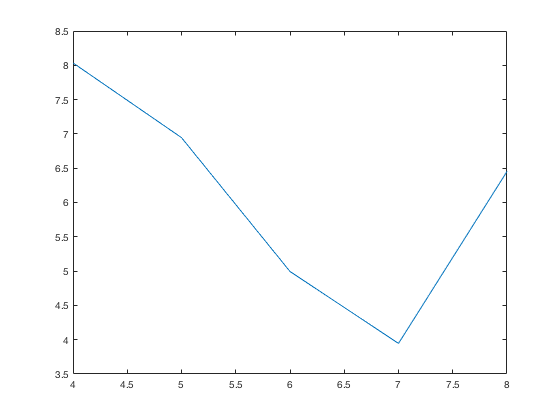


% Calculate theta energy
boundTh = (XData >= 4 & XData <= 8); % freq range of theta wave
Fth = XData(boundTh);
Pth = YData(boundTh); % power density range of theta wave
Eth = trapz(Fth, Pth); % energy of theta wave

figure
plot(Fth, Pth)


% Calculate ratio of alpha to beta
R = Ea / Eb;

Features = [Ea Eb Eth R] % extracted features forms a 'High Dimensional Feature Space'

Features =    23.7122  -32.8262   23.1295   -0.7224
